# **MATLAB的符号工具箱及其应用**

**        利用这个工具箱可以对函数进行微分、偏微分和极限的计算，定积分和不定积分的计算，还可以求解代数方程和微分方程，对函数进行积分变换等。**

**1.表达式的化简和替换**

- **pretty函数可将符号表达式以美观的形式呈现出来**

syms a b c
x1=(-b+sqrt(b^2-4*a*c))/(2*a);
x2=(-b-sqrt(b^2-4*a*c))/(2*a);
pretty(x1); pretty(x2);

            2
  b - sqrt(b  - 4 a c)
- --------------------
           2 a

            2
  b + sqrt(b  - 4 a c)
- --------------------
           2 a



- **simplify函数可将表达式化简**

syms x
y=(cos(x))^2+(sin(x))^2;
simplify(y)

$$ans = 1$$

- **subs函数可执行替换命令**

syms x
f=2*x^2-3*x+1;
subs(f,1/3)

$$ans = \frac{2}{9}$$

- **公共表达式替换命令subexpr **

syms a b c d      x
t = solve(a*x^3+b*x^2+c*x+d==0,x);       %求一元三次方程的根
[r,s] = subexpr(t,'s')                    %对结果进行化简，提取公共表达式，用s表示

$$r = \left(\begin{array}{c} \mathrm{root}\left(a\,{z_{1}}^{3}+b\,{z_{1}}^{2}+c\,z_{1}+d,z_{1},1\right)\\ \mathrm{root}\left(a\,{z_{1}}^{3}+b\,{z_{1}}^{2}+c\,z_{1}+d,z_{1},2\right)\\ \mathrm{root}\left(a\,{z_{1}}^{3}+b\,{z_{1}}^{2}+c\,z_{1}+d,z_{1},3\right) \end{array}\right)$$

 
s =
 
[ empty sym ]
 


**2.微积分运算**

- **偏微分运算**

syms x y
f=sin(x)^2+cos(y)^2;
diff(f)

$$ans = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

- **指定变量做偏微分运算**

syms x y
f=sin(x)^2+cos(y)^2;
diff(f,y)

$$ans = -2\,\cos\left(y\right)\,\sin\left(y\right)$$

- **做高阶导数运算**

syms x y
f=sin(x)^2+cos(y)^2;
diff(f,y,2)

$$ans = 2\,{\sin\left(y\right)}^{2}-2\,{\cos\left(y\right)}^{2}$$

- **int定积分和不定积分**

syms x
f=sin(x)^2;
int(f)

$$ans = \frac{x}{2}-\frac{\sin\left(2\,x\right)}{4}$$

- **Int不定积分和定积分运算**

syms x y n
f=x^n+y^n;
int(f)

$$ans = x\,y^{n}+\frac{x\,x^{n}}{n+1}$$

- **指定变量做不定积分**

syms x y n
f=x^n+y^n;
int(f,y)

$$ans = x^{n}\,y+\frac{y\,y^{n}}{n+1}$$

- **进行定积分运算**

syms x y n
f=x^n+y^n;
int(f,1,10)

$$ans = \left\{ \begin{array}{cl} \log\left(10\right)+\frac{9}{y} & \text{ if }n=-1\\ \frac{10\,10^{n}-1}{n+1}+9\,y^{n} & \text{ if }n\neq -1 \end{array}\right.$$

**3.方程求解**

- **solve求解代数方程**

syms x
solve(x^3-6*x^2==6-11*x)

$$ans = \left(\begin{array}{c} 1\\ 2\\ 3 \end{array}\right)$$

- **用solve进行求解，如果没有给出方程右侧的表达式，solve默认认为右侧即为0**

syms x
solve(x^3-6*x^2-6)

$$ans = \left(\begin{array}{c} \mathrm{root}\left({z_{1}}^{3}-6\,{z_{1}}^{2}-6,z_{1},1\right)\\ \mathrm{root}\left({z_{1}}^{3}-6\,{z_{1}}^{2}-6,z_{1},2\right)\\ \mathrm{root}\left({z_{1}}^{3}-6\,{z_{1}}^{2}-6,z_{1},3\right) \end{array}\right)$$

- **用solve进行求解，当方程中有多个符号变量时，必须指定对哪个变量进行求解**

syms x y
solve(6*x^2-6*x^2*y+x*y^2-x*y+y^3-y^2==0, y)

$$ans = \left(\begin{array}{c} 1\\ 2\,x\\ -3\,x \end{array}\right)$$

- **solve求解代数方程或方程组**

syms x y z
[x y z]=solve(z==4*x, x==y, z==x^2+y^2)

$$x = \left(\begin{array}{c} 0\\ 2 \end{array}\right)$$

$$y = \left(\begin{array}{c} 0\\ 2 \end{array}\right)$$

$$z = \left(\begin{array}{c} 0\\ 8 \end{array}\right)$$

- **如果要改变solve返回的根的顺序，可以在方程组后面把变量顺序指定**

syms x y z
[y z x]=solve(z==4*x, x==y, z==x^2+y^2, y, z, x)

$$y = \left(\begin{array}{c} 0\\ 2 \end{array}\right)$$

$$z = \left(\begin{array}{c} 0\\ 8 \end{array}\right)$$

$$x = \left(\begin{array}{c} 0\\ 2 \end{array}\right)$$

- **dsolve常微分方程求解**

syms y(t)
dsolve(diff(y)==y)

$$ans = C_{1}\,{\mathrm{e}}^{t}$$

- **dsolve常微分方程求解，给出了初始条件**

syms x(s) a
x = dsolve(diff(x) == -a*x, x(0) == 1)

$$x = {\mathrm{e}}^{-a\,s}$$

- **常微分方程**

syms f(t) g(t)
S = dsolve(diff(f) == f + g, diff(g) == -f + g,f(0) == 1,g(0) == 2);
[S.g;S.f]

$$ans = \left(\begin{array}{c} 2\,{\mathrm{e}}^{t}\,\cos\left(t\right)-{\mathrm{e}}^{t}\,\sin\left(t\right)\\ {\mathrm{e}}^{t}\,\cos\left(t\right)+2\,{\mathrm{e}}^{t}\,\sin\left(t\right) \end{array}\right)$$

**4.绘制符号函数的图像**

- **ezplot绘制曲线**

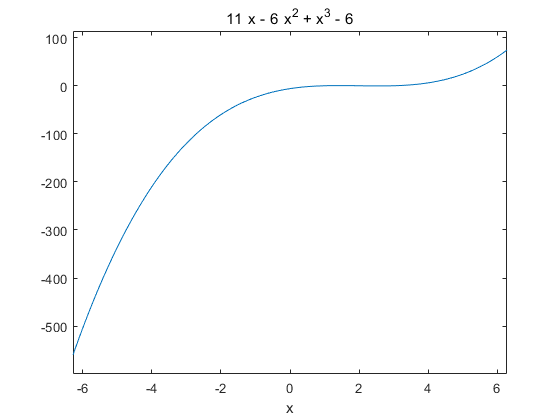

figure; 
syms x
ezplot(x^3-6*x^2+11*x-6);
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **ezplot绘制曲线，在给定的变量的区间绘制f对应的隐函数**

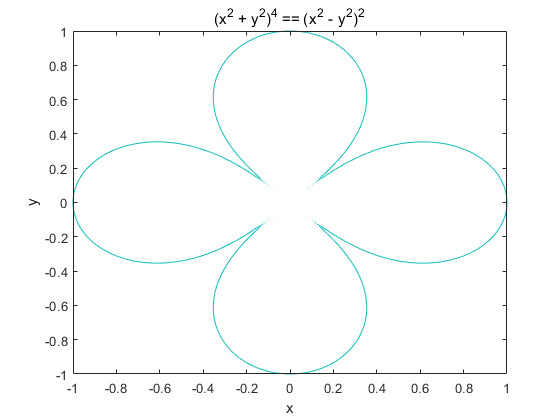

figure; 
syms x y
ezplot((x^2+y^2)^4==(x^2-y^2)^2, [-1 1])
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **ezplot绘制曲线，给定的参变量的区间绘制曲线**

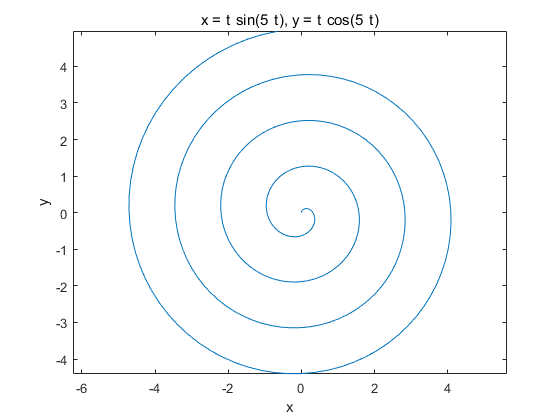

figure; 
syms t
x=t*sin(5*t);
y=t*cos(5*t);
ezplot(x,y,[0 5]);
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **ezplot3(x,y,z,[tmin,tmax])，绘制参变量t确定的三维空间曲线**

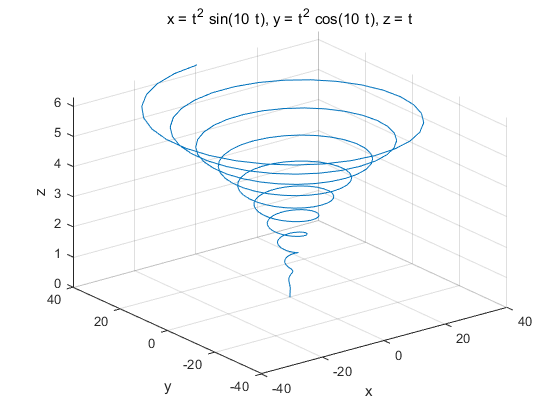

figure; 
syms t
ezplot3(t^2*sin(10*t), t^2*cos(10*t), t);
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **ezsurf(f,domain)， 在指定的区域内绘制函数f对应的曲面**

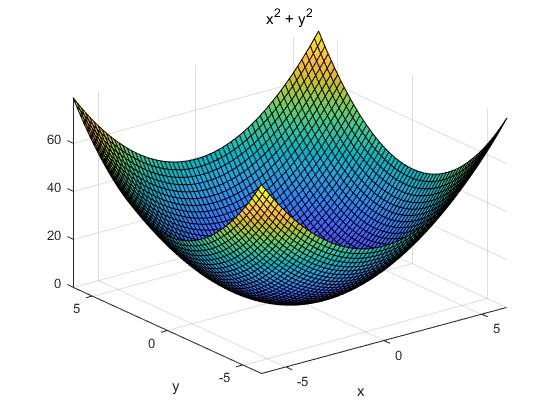

figure; 
syms x y
ezsurf(x^2+y^2)
set(gcf,'Visible','on');   	    %强制图片弹出显示

**5.正交坐标系与直角坐标系下材料张量的转换**

- **利用符号推演通过柱坐标系下的表达式推出直角坐标系的表达式**

syms x y z rho phi       	%坐标变量定义
syms er ep ez           	%材料参数定义
x=rho*cos(phi);         	%变量关系定义
y=rho*sin(phi);
R=[rho phi z];
X=[x; y; z];
T=jacobian(X,R);       	%雅克比矩阵计算
H=diag([1 1/rho 1]);     	%拉梅系数矩阵
T=H*T.';
epsilon=diag([er ep ez]);
epsilon=T.'*epsilon*T;    	%推算结果
simplify(epsilon)          	%结果化简

$$ans = \left(\begin{array}{ccc} \mathrm{er}+\mathrm{ep}\,{\sin\left(\varphi \right)}^{2}-\mathrm{er}\,{\sin\left(\varphi \right)}^{2} & -\frac{\sin\left(2\,\varphi \right)\,\left(\mathrm{ep}-\mathrm{er}\right)}{2} & 0\\ -\frac{\sin\left(2\,\varphi \right)\,\left(\mathrm{ep}-\mathrm{er}\right)}{2} & \mathrm{ep}-\mathrm{ep}\,{\sin\left(\varphi \right)}^{2}+\mathrm{er}\,{\sin\left(\varphi \right)}^{2} & 0\\ 0 & 0 & \mathrm{ez} \end{array}\right)$$

- **利用符号推演通过球坐标系下的表达式推出直角坐标系的表达式**

syms x y z r phi theta           	%坐标变量定义
syms er et ep                  	%材料参数定义
x=r*sin(theta)*cos(phi);         	%变量关系定义，x
y=r*sin(theta)*sin(phi);	%变量关系定义，y
z=r*cos(theta);		%变量关系定义，z
R=[r theta phi];
X=[x; y; z];
T=jacobian(X,R);             	%雅克比矩阵计算
H=diag([1 1/r 1/(r*sin(theta))]);  	%拉梅系数矩阵
T=H*T.';
epsilon=diag([er et ep]);
epsilon=T.'*epsilon*T;          	%推算结果
simplify(epsilon)                	%结果化简

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \mathrm{et}\,{\cos\left(\varphi \right)}^{2}\,{\cos\left(\theta \right)}^{2}+\mathrm{er}\,{\cos\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2}+\mathrm{ep}\,{\sin\left(\varphi \right)}^{2} & \sigma_{3} & \sigma_{2}\\ \sigma_{3} & \mathrm{ep}\,{\cos\left(\varphi \right)}^{2}+\mathrm{et}\,{\cos\left(\theta \right)}^{2}\,{\sin\left(\varphi \right)}^{2}+\mathrm{er}\,{\sin\left(\varphi \right)}^{2}\,{\sin\left(\theta \right)}^{2} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & \mathrm{er}-\sigma_{5}+\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\,\left(\mathrm{er}-\mathrm{et}\right)\\ \sigma_{2}=\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(\mathrm{er}-\mathrm{et}\right)\\ \sigma_{3}=-\cos\left(\varphi \right)\,\sin\left(\varphi \right)\,\left(\mathrm{ep}-\mathrm{et}-\sigma_{5}+\sigma_{4}\right)\\ \sigma_{4}=\mathrm{et}\,{\sin\left(\theta \right)}^{2}\\ \sigma_{5}=\mathrm{er}\,{\sin\left(\theta \right)}^{2} \end{array}$$

**6.变换电磁理论的符号推演**

- **柱状隐形设置**

syms x y z x1 y1 z1 rho phi rho1 phi1 eps a b c       	%坐标变量定义
x=rho*cos(phi); x1=rho1*cos(phi1);               	% 直角坐标系与柱坐标系间的关系
y=rho*sin(phi); y1=rho1*sin(phi1);                 	% 直角坐标系与柱坐标系间的关系
R=[rho phi z];    R1=[rho1 phi1 z1];               	%定义几个向量
X=[x; y; z];      X1=[x1; y1; z1];
det1=det(jacobian(X1,R1));                       	%计算行列式的值
rho1=rho*(b-a)/b+a; phi1=phi; z1=z;               	%虚拟空间与物理空间的变换关系
R1=[rho1 phi1 z1];                              
T=jacobian(X,R);                               	%雅克比矩阵计算
H=diag([1 rho 1]);                              	%拉梅系数矩阵
H1=diag([1 rho1 1]);                            	%拉梅系数矩阵
B=H1*jacobian(R1,R);                          	%计算矩阵B
det2=det(jacobian(R1,R));                        	%计算行列式
eps1=eps*B*inv(H*H)*B.'*det(jacobian(X,R))/det1/det2;      %光学变换的公式
clear phi1 z1 rho1                               	%清除物理空间的变量  
syms phi1 z1 rho1                              	%重新定义这些变量 
phi=phi1;z=z1;rho=(rho1-a)*b/(b-a);               	%虚拟空间与物理空间的变换关系 
simplify(subs(eps1))           %结果化简,并且将最终结果用物理空间的变量表示出来

$$ans = \left(\begin{array}{ccc} -\frac{\mathrm{eps}\,\left(a-\rho_{1}\right)}{\rho_{1}} & 0 & 0\\ 0 & -\frac{\mathrm{eps}\,\rho_{1}}{a-\rho_{1}} & 0\\ 0 & 0 & -\frac{b^{2}\,\mathrm{eps}\,\left(a-\rho_{1}\right)}{\rho_{1}\,{\left(a-b\right)}^{2}} \end{array}\right)$$

**7.介电常数张量的对角化**

        
$$\varepsilon_1 =\left\lbrack \begin{array}{ccc}
\varepsilon_{\textrm{xx}}  & \varepsilon_{\textrm{xy}}  & \varepsilon_{\textrm{xz}} \\
\varepsilon_{\textrm{yx}}  & \varepsilon_{\textrm{yy}}  & \varepsilon_{\textrm{yz}} \\
\varepsilon_{\textrm{zx}}  & \varepsilon_{\textrm{zy}}  & \varepsilon_{\textrm{zz}} 
\end{array}\right\rbrack$$
 

        
$$\varepsilon_2 =\left\lbrack \begin{array}{ccc}
\varepsilon_{\textrm{xx}}  & \varepsilon_{\textrm{xy}}  & 0\\
\varepsilon_{\textrm{yx}}  & \varepsilon_{\textrm{yy}}  & 0\\
0 & 0 & \varepsilon_{\textrm{zz}} 
\end{array}\right\rbrack$$


- **一般情况下的张量对角化**

syms epxx epxy epxz epyy epyz epzz                    %定义符号变量
eps=[epxx epxy epxz; epxy epyy epyz; epxz epyz epzz];     %对应varepsilon1
[V D]=eig(eps)                                     %计算本征值和本征向量

$$D = \begin{array}{l} \left(\begin{array}{ccc} \frac{\mathrm{epxx}}{3}+\frac{\mathrm{epyy}}{3}+\frac{\mathrm{epzz}}{3}+\frac{\sigma_{3}}{\sigma_{2}}+\sigma_{2} & 0 & 0\\ 0 & \frac{\mathrm{epxx}}{3}+\frac{\mathrm{epyy}}{3}+\frac{\mathrm{epzz}}{3}-\frac{\sigma_{3}}{2\,\sigma_{2}}-\frac{\sigma_{2}}{2}-\sigma_{1} & 0\\ 0 & 0 & \frac{\mathrm{epxx}}{3}+\frac{\mathrm{epyy}}{3}+\frac{\mathrm{epzz}}{3}-\frac{\sigma_{3}}{2\,\sigma_{2}}-\frac{\sigma_{2}}{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\frac{\sigma_{3}}{\sigma_{2}}-\sigma_{2}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(\sqrt{{\left(\sigma_{4}+\sigma_{8}+\sigma_{7}+\sigma_{6}-\sigma_{5}-\mathrm{epxy}\,\mathrm{epxz}\,\mathrm{epyz}-\frac{\mathrm{epxx}\,\mathrm{epyy}\,\mathrm{epzz}}{2}\right)}^{2}-{\sigma_{3}}^{3}}-\sigma_{4}-\sigma_{8}-\sigma_{7}-\sigma_{6}+\sigma_{5}+\mathrm{epxy}\,\mathrm{epxz}\,\mathrm{epyz}+\frac{\mathrm{epxx}\,\mathrm{epyy}\,\mathrm{epzz}}{2}\right)}^{1/3}\\ \sigma_{3}=\frac{{\mathrm{epxy}}^{2}}{3}-\frac{\mathrm{epxx}\,\mathrm{epzz}}{3}-\frac{\mathrm{epyy}\,\mathrm{epzz}}{3}-\frac{\mathrm{epxx}\,\mathrm{epyy}}{3}+\frac{{\mathrm{epxz}}^{2}}{3}+\frac{{\mathrm{epyz}}^{2}}{3}+\frac{{\left(\mathrm{epxx}+\mathrm{epyy}+\mathrm{epzz}\right)}^{2}}{9}\\ \sigma_{4}=\frac{\left(\mathrm{epxx}+\mathrm{epyy}+\mathrm{epzz}\right)\,\left(-{\mathrm{epxy}}^{2}-{\mathrm{epxz}}^{2}-{\mathrm{epyz}}^{2}+\mathrm{epxx}\,\mathrm{epyy}+\mathrm{epxx}\,\mathrm{epzz}+\mathrm{epyy}\,\mathrm{epzz}\right)}{6}\\ \sigma_{5}=\frac{{\left(\mathrm{epxx}+\mathrm{epyy}+\mathrm{epzz}\right)}^{3}}{27}\\ \sigma_{6}=\frac{{\mathrm{epxy}}^{2}\,\mathrm{epzz}}{2}\\ \sigma_{7}=\frac{{\mathrm{epxz}}^{2}\,\mathrm{epyy}}{2}\\ \sigma_{8}=\frac{\mathrm{epxx}\,{\mathrm{epyz}}^{2}}{2} \end{array}$$

- **直角坐标系中二维情况下的张量对角化**

syms epxx epxy epyy epzz                  	%定义符号变量
eps=[epxx epxy 0; epxy epyy 0; 0 0 epzz];      	%对应varepsilon2
[V D]=eig(eps)                          	%计算本征值和本征函数

$$V = \left(\begin{array}{ccc} 0 & \frac{\frac{\mathrm{epxx}}{2}+\frac{\mathrm{epyy}}{2}-\frac{\sqrt{{\mathrm{epxx}}^{2}-2\,\mathrm{epxx}\,\mathrm{epyy}+4\,{\mathrm{epxy}}^{2}+{\mathrm{epyy}}^{2}}}{2}}{\mathrm{epxy}}-\frac{\mathrm{epyy}}{\mathrm{epxy}} & \frac{\frac{\mathrm{epxx}}{2}+\frac{\mathrm{epyy}}{2}+\frac{\sqrt{{\mathrm{epxx}}^{2}-2\,\mathrm{epxx}\,\mathrm{epyy}+4\,{\mathrm{epxy}}^{2}+{\mathrm{epyy}}^{2}}}{2}}{\mathrm{epxy}}-\frac{\mathrm{epyy}}{\mathrm{epxy}}\\ 0 & 1 & 1\\ 1 & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} \mathrm{epzz} & 0 & 0\\ 0 & \frac{\mathrm{epxx}}{2}+\frac{\mathrm{epyy}}{2}-\frac{\sqrt{{\mathrm{epxx}}^{2}-2\,\mathrm{epxx}\,\mathrm{epyy}+4\,{\mathrm{epxy}}^{2}+{\mathrm{epyy}}^{2}}}{2} & 0\\ 0 & 0 & \frac{\mathrm{epxx}}{2}+\frac{\mathrm{epyy}}{2}+\frac{\sqrt{{\mathrm{epxx}}^{2}-2\,\mathrm{epxx}\,\mathrm{epyy}+4\,{\mathrm{epxy}}^{2}+{\mathrm{epyy}}^{2}}}{2} \end{array}\right)$$

**8.椭圆坐标系的MATLAB辅助分析**

- **椭球坐标系中的坐标平面**

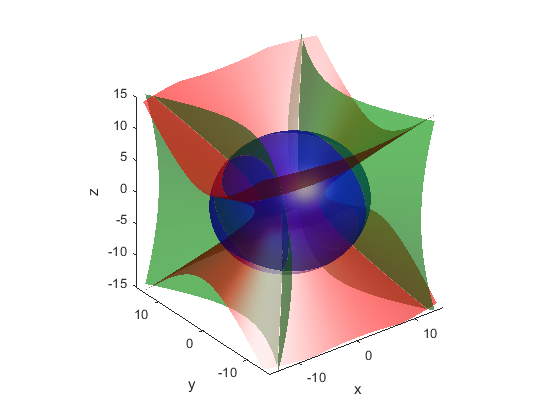

a=7;b=5;c=3;                          %设置椭球系的三个常数
x=6;y=6;z=6;                          %任意选择一点（6,6,6）
syms u;                               %定义符号变量u
S=solve(x^2/(a^2+u)+y^2/(b^2+u)+z^2/(c^2+u)==1,u);   %求解u的三个实数解
S=double(S);                          %将解由符号形式转化为数值
ksi=S(1);eta=S(2);zeta=S(3);              %分别赋予ksi，eta，zeta等三个椭球系下的坐标
f1 = @(x,y,z) x.^2/(a^2+ksi)+y.^2/(b^2+ksi)+z.^2/(c^2+ksi)-1;      % 函数表达式
figure; 
[x,y,z] = meshgrid(-15:.2:15,-15:.2:15,-15:.2:15);                 % 画图范围
v = f1(x,y,z);                           %定义三元函数f1
h = patch(isosurface(x,y,z,v,0));            %绘制v=0的等值面，即（5-22）对应坐标平面
set(h,'FaceColor','r','EdgeColor','none');      %设置坐标面的属性
xlabel('x');ylabel('y');zlabel('z');            %标注坐标轴
hold on;                               %准备继续绘制其他曲面
%以下用类似的方法，分别绘制eta和zeta等于常数的坐标曲面
f2 = @(x,y,z) x.^2/(a^2+eta)+y.^2/(b^2+eta)+z.^2/(c^2+eta)-1;        % 函数表达式
[x,y,z] = meshgrid(-15:.5:15,-15:.5:15,-15:.5:15);                   % 画图范围
v = f2(x,y,z);
h = patch(isosurface(x,y,z,v,0)); 
isonormals(x,y,z,v,h)              
set(h,'FaceColor','g','EdgeColor','none');
f3 = @(x,y,z) x.^2/(a^2+zeta)+y.^2/(b^2+zeta)+z.^2/(c^2+zeta)-1;      % 函数表达式
[x,y,z] = meshgrid(-15:.2:15,-15:.2:15,-15:.2:15);                    % 画图范围
v = f3(x,y,z);
h = patch(isosurface(x,y,z,v,0)); 
set(h,'FaceColor','b','EdgeColor','none');
alpha(0.6);                                                  %曲面半透明     
view(3); axis equal; camlight; lighting gouraud;                      %其他辅助设置
axis vis3d;
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **利用符号计算工具，计算表达式**

syms a b c x y z ksi eta zeta       	%定义符号变量
	%求解三元方程组，得到x、y、z的表达式
S=solve(x^2/(a^2+ksi)+y^2/(b^2+ksi)+z^2/(c^2+ksi)==1,...
x^2/(a^2+eta)+y^2/(b^2+eta)+z^2/(c^2+eta)==1,...
x^2/(a^2+zeta)+y^2/(b^2+zeta)+z^2/(c^2+zeta)==1);
	%分别显示x、y、z的表达形式
pretty(S.x(1))                  	%用直观的形式，显示x的一个根，下同

     /   2          2          2         \
     | (a  + eta) (a  + ksi) (a  + zeta) |
-sqrt| --------------------------------- |
     \  (a + b) (a + c) (a - b) (a - c)  /



pretty(S.y(1))

    /     2          2          2         \
    |   (b  + eta) (b  + ksi) (b  + zeta) |
sqrt| - --------------------------------- |
    \    (a + b) (b + c) (a - b) (b - c)  /



pretty(S.z(1))

    /   2          2          2         \
    | (c  + eta) (c  + ksi) (c  + zeta) |
sqrt| --------------------------------- |
    \  (a + c) (b + c) (a - c) (b - c)  /



- **利用符号工具箱推演托球坐标系中的拉梅系数**

syms a b c x y z ksi eta zeta                              	%定义符号变量
S=solve(x^2/(a^2+ksi)+y^2/(b^2+ksi)+z^2/(c^2+ksi)==1,...
x^2/(a^2+eta)+y^2/(b^2+eta)+z^2/(c^2+eta)==1,...
x^2/(a^2+zeta)+y^2/(b^2+zeta)+z^2/(c^2+zeta)==1);  	%求x、y、z的表达式
x=(S.x(1));                                            	%x的表达式  
y=(S.y(1));                                            	%y的表达式
z=(S.z(1));                                            	%z的表达式
R_ksi=sqrt((diff(x,ksi))^2+(diff(y,ksi))^2+(diff(z,ksi))^2);      	%计算拉梅系数
R_eta=sqrt((diff(x,eta))^2+(diff(y,eta))^2+(diff(z,eta))^2);
R_zeta=sqrt((diff(x,zeta))^2+(diff(y,zeta))^2+(diff(z,zeta))^2);
pretty(simplify(R_ksi))                                    	%直观显示拉梅系数

    /        (eta - ksi) (ksi - zeta)      \
sqrt| - ---------------------------------- |
    |     2          2          2          |
    \   (a  + ksi) (b  + ksi) (c  + ksi) 4 /



pretty(simplify(R_eta))

    /      (eta - ksi) (eta - zeta)      \
sqrt| ---------------------------------- |
    |   2          2          2          |
    \ (a  + eta) (b  + eta) (c  + eta) 4 /



pretty(simplify(R_zeta))

    /       (eta - zeta) (ksi - zeta)       \
sqrt| ------------------------------------- |
    |   2           2           2           |
    \ (a  + zeta) (b  + zeta) (c  + zeta) 4 /



**9.内部匀质化理论及其MATLAB分析**

- **求解方程**

syms a ep_1 ep_2 ep_b b E0 b ep_e
A = [a  -a  -1/a  0; 
ep_1   -ep_2   ep_2/a^2   0;
0  b  1/b  -1/b;
0  ep_2  -ep_2/b^2  ep_b/b^2];	%方程系数矩阵
m = [0;0;-E0*b;-ep_b*E0];	%方程右侧部分
C = A\m;                           	%左除的位置向量
D = C(4);	%D的结果
D_m = D/(E0*b^2);	%将D化简
[N1, D1]=numden(D_m)	%D_m的分子和分母，用于验证

$$N1 = b^{2}\,{{\mathrm{ep}}_{2}}^{2}-a^{2}\,{{\mathrm{ep}}_{2}}^{2}+a^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}+a^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}-a^{2}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}+b^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}-b^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}-b^{2}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}$$

$$D1 = b^{2}\,{{\mathrm{ep}}_{2}}^{2}-a^{2}\,{{\mathrm{ep}}_{2}}^{2}+a^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}-a^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+a^{2}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}+b^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}+b^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+b^{2}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}$$

ep_e = (1 + D_m)/(1 - D_m);	%等效介电常数
[N2,D2] = numden(ep_e)	%ep_e的分子和分母

$$N2 = -a^{2}\,{{\mathrm{ep}}_{2}}^{2}+{\mathrm{ep}}_{1}\,a^{2}\,{\mathrm{ep}}_{2}+b^{2}\,{{\mathrm{ep}}_{2}}^{2}+{\mathrm{ep}}_{1}\,b^{2}\,{\mathrm{ep}}_{2}$$

$$D2 = a^{2}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}-a^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+b^{2}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+b^{2}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}$$

- **对方程以及介电常数进行求解**

syms a ep_1 ep_2 ep_b b E0 b ep_e
A = [a  -a  -1/(a^2)  0; 
    ep_1   -ep_2   2*ep_2/a^3   0;
    0  b  1/(b^2)  -1/(b^2);
    0  ep_2  -2*ep_2/b^3  2*ep_b/b^3];   	%定义系数矩阵
m = [0;0;-E0*b;-ep_b*E0];                 	%方程右侧部分
C = A\m;                               	%求未知数向量[A B C D]^T
D = C(4);                              	%D的表达式
D_m = D/(E0*b^3);                      	%简化D 
[N1,D1] = numden(D_m)                   	%求D_m的分子和分母

$$N1 = 2\,b^{3}\,{{\mathrm{ep}}_{2}}^{2}-2\,a^{3}\,{{\mathrm{ep}}_{2}}^{2}+2\,a^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}+a^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}-a^{3}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}+b^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}-b^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}-2\,b^{3}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}$$

$$D1 = 2\,b^{3}\,{{\mathrm{ep}}_{2}}^{2}-2\,a^{3}\,{{\mathrm{ep}}_{2}}^{2}+2\,a^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}-2\,a^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+2\,a^{3}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}+b^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{2}+2\,b^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+4\,b^{3}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}$$

ep_e = (1 + 2*D_m)/(1 - D_m);             	%式（5-47）
[N2,D2] = numden(ep_e)                  	%求ep_e的分子和分母，以便于验证

$$N2 = -2\,a^{3}\,{{\mathrm{ep}}_{2}}^{2}+2\,{\mathrm{ep}}_{1}\,a^{3}\,{\mathrm{ep}}_{2}+2\,b^{3}\,{{\mathrm{ep}}_{2}}^{2}+{\mathrm{ep}}_{1}\,b^{3}\,{\mathrm{ep}}_{2}$$

$$D2 = a^{3}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}-a^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+b^{3}\,{\mathrm{ep}}_{1}\,{\mathrm{ep}}_{b}+2\,b^{3}\,{\mathrm{ep}}_{2}\,{\mathrm{ep}}_{b}$$

- **利用matlab对方程求解得到D**

syms ep_e ep_0 N1  R1                  	%定义符号变量
A = [1 N1/2;ep_e ep_0*N1/2-ep_0/R1];      	%定义系数矩阵
m = [1;ep_0];                           	%定义方程右侧的列向量
C = A\m;                               	%求解代数方程
D = C(2);                               	%D的表达式
pretty(D)                               	%用直观的形式显示系数D

         2 R1 (ep_0 - ep_e)
- --------------------------------
  2 ep_0 - N1 R1 ep_0 + N1 R1 ep_e



- **利用matlab对方程进行符号推演**

syms ep_1 ep_2 ep_0 N1 N2 R1 R2 ep_r ep_e      %定义符号变量
A = [-1 1 -N2/2 0;
    -ep_2 ep_1 ep_1/R2-ep_1*N2/2 0;
    0 1 -N1/2 N1/2;
    0 ep_1 ep_1/R1-ep_1*N1/2 ep_0*N1/2-ep_0/R1];
m = [0;0;1;ep_0];
C = A\m;                                    %C=[C2 C1 D1 D0]
D0 = C(4);                                   %D0的表达式
A = [1 N1/2;ep_e ep_0*N1/2-ep_0/R1];
m = [1;ep_0];
C = A\m;
D = C(2);                                    %D的表达式
ep_r=solve(D==D0,ep_e, 'ReturnConditions', true);                       %求解方程，得到ep_e
pretty(simplify(ep_r.ep_e))                            %显示ep_e的表达式

ep_1 (2 R1 ep_1 - 2 R2 ep_1 + 2 R2 ep_2 + N1 R1 R2 ep_1 - N1 R1 R2 ep_2 - N2 R1 R2 ep_1 + N2 R1 R2 ep_2)
--------------------------------------------------------------------------------------------------------
                     R1 (2 ep_1 + N1 R2 ep_1 - N1 R2 ep_2 - N2 R2 ep_1 + N2 R2 ep_2)



**10.计算光场的分布情况**

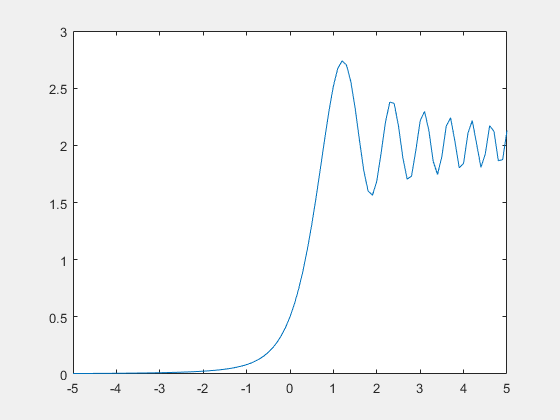

clc
clear
zeta=-5:0.1:5;                    	%定义zeta区间，它与x成正比
C=fresnelc(zeta);          %计算菲涅尔余弦积分值
S=fresnels(zeta);         	%计算菲尼尔正弦积分值
I0=1;
I=(C+1/2).^2+(S+1/2).^2;         	%计算光场强度
figure; 
plot(zeta,I);                       	%绘制曲线
set(gcf,'Visible','on');   	    %强制图片弹出显示

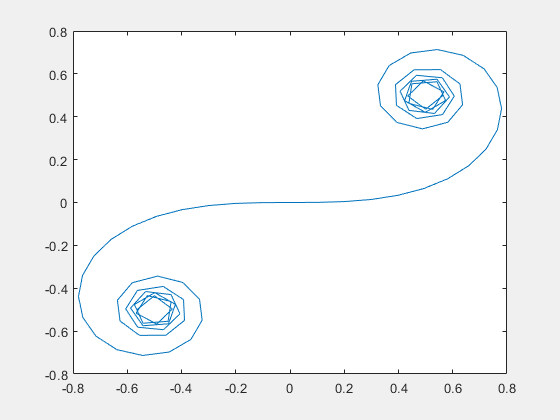

figure; 
plot(C,S);               	%绘制考纽螺线
set(gcf,'Visible','on');   	    %强制图片弹出显示